#  Running MONAI model inference in MATLAB

Setting up the python version and environment:

terminate(pyenv)
pyversion('/Users/amithkamath/opt/anaconda3/envs/matlab-env/bin/python')

Importing a custom module to interact between MATLAB and functions written to load the U-Net model, and run inference.

py.importlib.import_module('monaiInference')

ans =   Python module with properties:

       create_model: [1×1 py.function]
         AsDiscrete: [1×1 py.abc.ABCMeta]
         test_model: [1×1 py.function]
               Norm: [1×1 py.monai.networks.layers.factories.LayerFactory]
              Image: [1×1 py.module]
              torch: [1×1 py.module]
               UNet: [1×1 py.type]
          inference: [1×1 py.function]
    decollate_batch: [1×1 py.function]
        Activations: [1×1 py.abc.ABCMeta]
              monai: [1×1 py.module]
            Compose: [1×1 py.abc.ABCMeta]

    <module 'monaiInference' from '/Users/amithkamath/repo/monai-from-matlab/monaiInference.py'>


Creating the monai version of the U-Net in MATLAB using the create_model function:

monaiUNet = py.monaiInference.create_model("heart-2d-model.pth")

sys:1: UserWarning: TypedStorage is deprecated. It will be removed in the future and UntypedStorage will be the only storage class. This should only matter to you if you are using storages directly.  To access UntypedStorage directly, use tensor.untyped_storage() instead of tensor.storage()


monaiUNet =   Python UNet with properties:

      adn_ordering: [1×3 py.str]
          channels: [1×6 py.tuple]
     num_res_units: [1×1 py.int]
       kernel_size: [1×1 py.int]
          training: 1
    up_kernel_size: [1×1 py.int]
           dropout: 0
      out_channels: [1×1 py.int]
        dimensions: [1×1 py.int]
              bias: 0
               act: [1×4 py.str]
           strides: [1×5 py.tuple]
       in_channels: [1×1 py.int]
              norm: [1×5 py.str]

    UNet(
      (model): Sequential(
        (0): Convolution(
          (conv): Conv2d(1, 16, kernel_size=(3, 3), stride=(2, 2), padding=(1, 1), bias=False)
          (adn): ADN(
            (N): BatchNorm2d(16, eps=1e-05, momentum=0.1, affine=True, track_running_stats=True)
            (D): Dropout(p=0.0, inplace=False)
            (A): ReLU()
          )
        )
        (1): SkipConnection(
          (submodule): Sequenti

Reading image data (the size of which corresponds to the model previously trained):

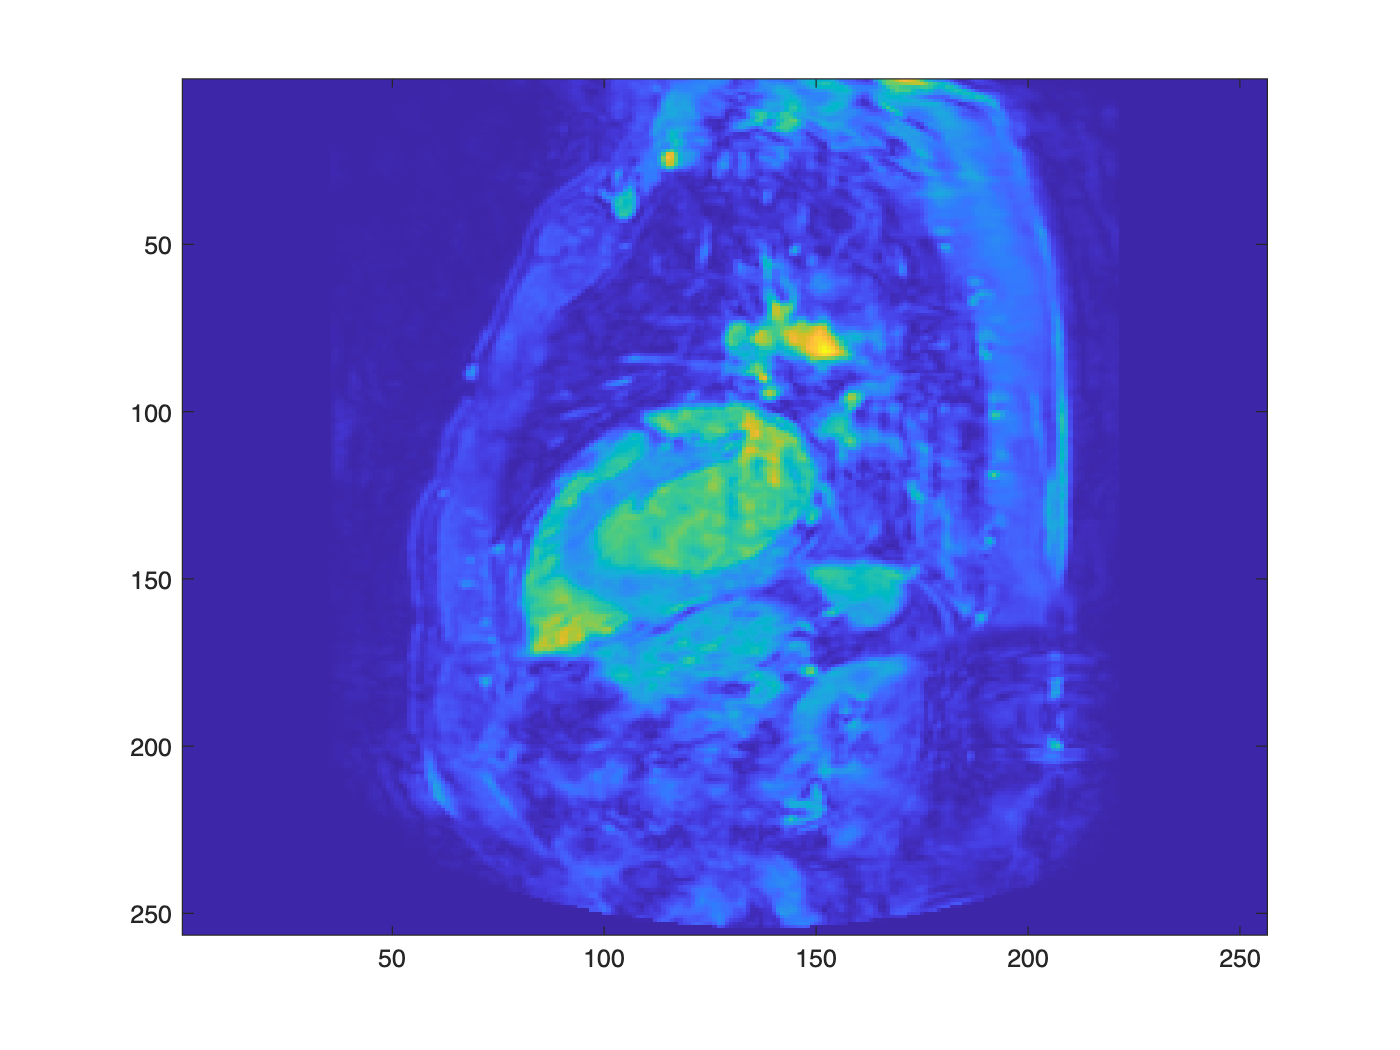

im = imread("data/images/image_0000.png");
imagesc(im)

im_channel = single(reshape(im, [1, 1, 256, 256]));
im_channel = im_channel ./ 255;

Running inference using the python function from the custom imported module:

seg = py.monaiInference.inference(monaiUNet, py.torch.tensor(py.numpy.array(im_channel)));

Displaying the segmentation results along with the image:

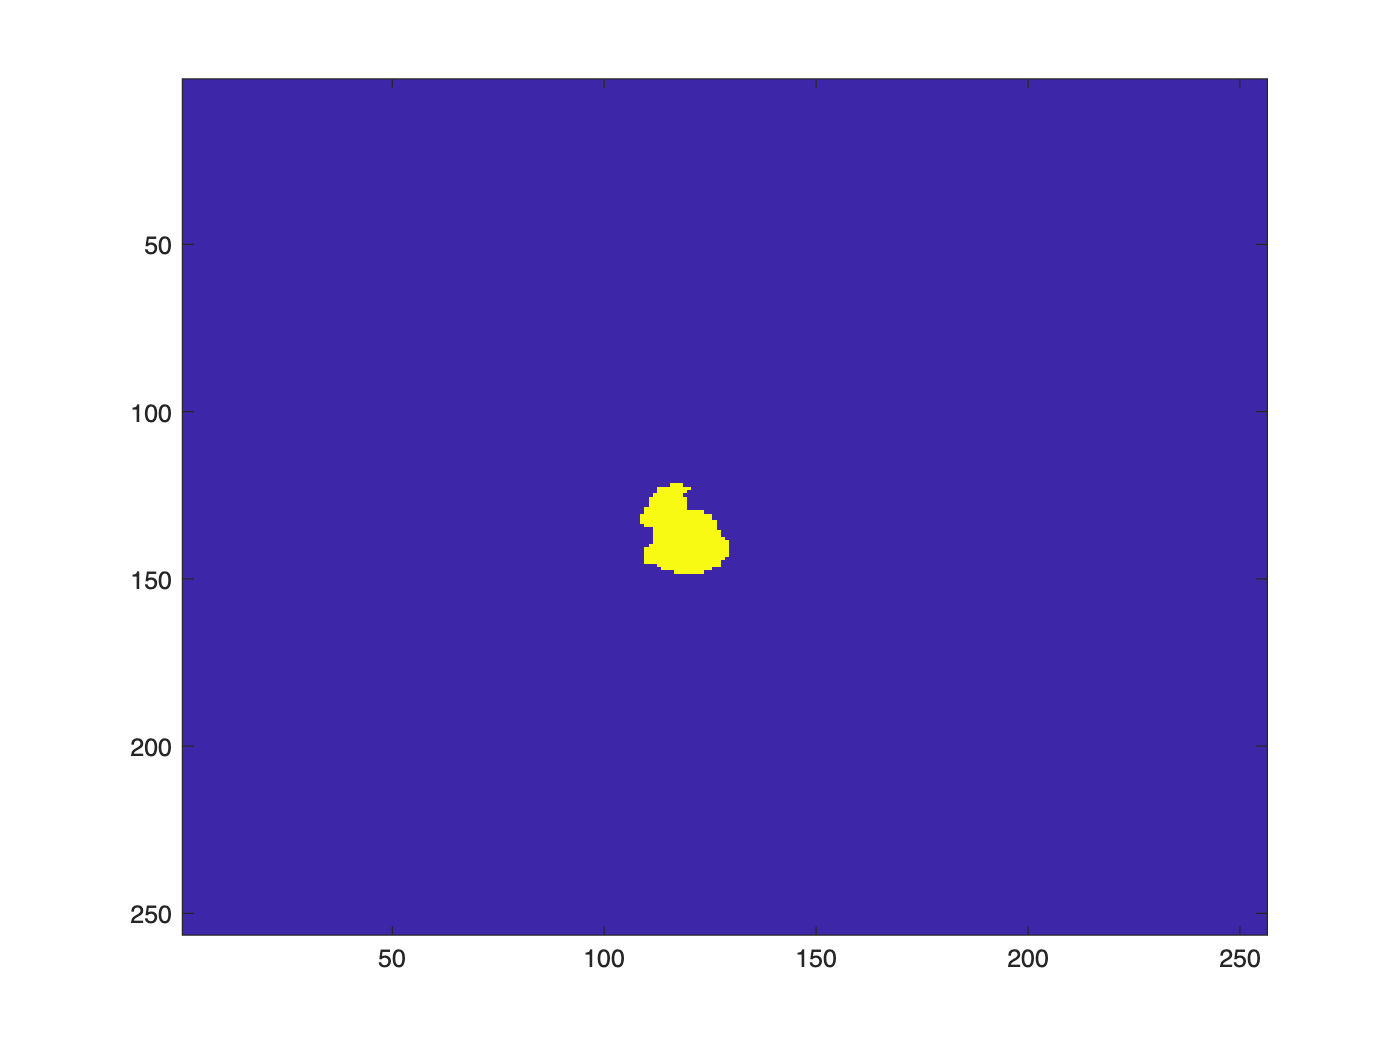

seg = squeeze(single(py.numpy.array(seg)));
imagesc(seg)